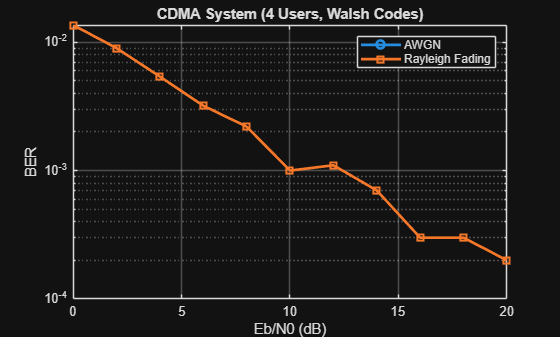

clc; clear; close all;

%% Parameters
numUsers = 4;          % Number of users
N = 1e4;               % Bits per user
EbN0_dB = 0:2:20;

spreadingFactor = 8;   % Length of Walsh code

% Generate Walsh codes
H = hadamard(spreadingFactor);
codes = H(1:numUsers, :);   % Assign orthogonal codes

% Generate bits for all users
bits = randi([0 1], numUsers, N);
symbols = 2*bits - 1;   % BPSK

ber_awgn = zeros(size(EbN0_dB));
ber_rayleigh = zeros(size(EbN0_dB));

%% ================= Simulation =================
for i = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(i)/10);
    noise_var = 1/(2*EbN0);
    
    error_awgn = 0;
    error_ray = 0;
    
    for k = 1:N
        
        %% -------- Transmitter --------
        tx_signal = zeros(1, spreadingFactor);
        
        for u = 1:numUsers
            tx_signal = tx_signal + symbols(u,k) * codes(u,:);
        end
        
        %% ================= AWGN =================
        noise = sqrt(noise_var)*randn(1, spreadingFactor);
        rx_awgn = tx_signal + noise;
        
        % Detect only User 1
        detected = sign(sum(rx_awgn .* codes(1,:)));
        if detected == 0, detected = 1; end
        
        if detected ~= symbols(1,k)
            error_awgn = error_awgn + 1;
        end
        
        %% ================= Rayleigh =================
        h = (randn + 1j*randn)/sqrt(2);
        rx_ray = h * tx_signal + noise;
        
        % Equalization
        rx_eq = real(rx_ray / h);
        
        detected = sign(sum(rx_eq .* codes(1,:)));
        if detected == 0, detected = 1; end
        
        if detected ~= symbols(1,k)
            error_ray = error_ray + 1;
        end
        
    end
    
    ber_awgn(i) = error_awgn / N;
    ber_rayleigh(i) = error_ray / N;
    
end

%% ================= Plot =================
figure;
semilogy(EbN0_dB, ber_awgn, 'o-', 'LineWidth', 2); hold on;
semilogy(EbN0_dB, ber_rayleigh, 's-', 'LineWidth', 2);

grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title(['CDMA System (', num2str(numUsers), ' Users, Walsh Codes)']);
legend('AWGN','Rayleigh Fading');